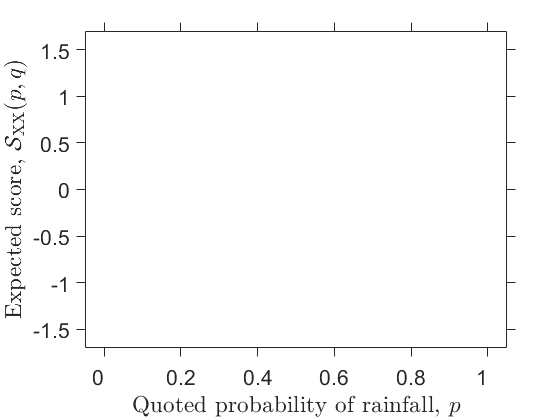

close all hidden
% Initialize
n = 101;                            % Number of values of q for animation
Q = linspace(0,1,n)';               % Q (= all values of q)
N = 1001;                           % Number of values of p for plotting
p1 = linspace(0,1,N)'; p2 = 1 - p1; % Rain/no rain, predicted
ES_min = -1.7; ES_max = -ES_min;    % Minimum and maximum of y-axis (Expected score) 
loc_legend = {'northeast','northwest'};
% % Endless loop
while 0 == 0
    % Change probability assigned to true event {1}
    for i = 1:n
        % Set true value of rain/no rain [q1,q2] (= scalars)
        q1 = Q(i); q2 = 1 - q1;         
        % Expected value of quadratic rule for discretized [p1,p2] values
        E_QS = q1 * (2*p1 - (p1.^2 + p2.^2)) + q2 * (2*p2 - (p1.^2 + p2.^2));
        % Expected value of spherical rule for discretized [p1,p2] values 
        E_SS = q1 * (p1 .* (p1.^2 + p2.^2).^(-1/2)) + q2 * (p2 .* (p1.^2 + p2.^2).^(-1/2));
        % Expected value of logarithmic rule for discretized [p1,p2] values
        E_LS = q1 * log10(p1) + q2 * log10(p2);
        % Plot expected scores for given value of [q1,q2] 
        h1 = plot(p1,E_QS,'g','linewidth',2); hold on; 
        h2 = plot(p1,E_LS,'r','linewidth',2);
        h3 = plot(p1,E_SS,'b','linewidth',2);
        % Plot true rainfall probability 
        h4 = line([q1 q1],[ES_min ES_max],'color','k','linestyle','--');
        % Plot x-label and y-label
        xlabel('Quoted probability of rainfall, $p$','interpreter',...
            'latex','fontsize',16);
        ylabel('Expected score, $\mathcal{S}_{\rm XX}(p,q)$','interpreter',...
            'latex','fontsize',16);
        set(gca,'fontsize',16,'tickdir','out','ticklength',[0.02 0.04]); 
        % axis equal % axis square
        % Plot legend
        h5 = legend('\color{green} quadratic','\color{red} logarithmic',...
            '\color{blue} spherical','box','off',...
            'Location',char(loc_legend((q1 > 0.5) + 1)),'fontsize',13);
        % Adjust axis
        axis([-0.05 1.05 ES_min ES_max]);
        % Change fontsize and tick direction and axis
        h6 = text(q1,-1.5,strcat('$q = $',num2str(q1,'%2.2f')),...
            'fontsize',16,'interpreter','latex',...
            'BackgroundColor','white');
        set(h6,'rotation',90);
        % Change x-ticks and values
        set(gca,'xtick',[0:0.2:1.0],'xticklabel',[0:0.2:1]);
        % Pause for a little bit
        pause(0.01);
        delete(h1); delete(h2); delete(h3); delete(h4); delete(h6);
    end

end